clc; clear; close all;


% Parameters
l_B = 0.132; % [m] Base langth. 13.2cm measured. 
l_P = 0.24; % [m] Pendulum length. 24cm measured.
I_B = 2*(1/12)*0.05*0.25^2; % [kg*m^2]Base, motor ang gerbox inertia (about mass centre)
I_P = (1/3)*0.010*0.25^2; % [kg*m^2] Pendulum inertia (about mass centre). Estimated with mass = 10g
L = 1.3/1000; % [Henry] Motor inductance. From random data sheet
R = 4.2; % [Omh] Motor resistance. From random data sheet
m_P = 0.026; % [kg] Pendulum mass. 26g measured
B_B = -100;%0.01; % [Nm*rad/s] Motor friction.
B_P = -0.005; % [Nm*rad/s] Penulum friction.
g = 9.81; % [m/s^2] gravety.
K_t = 0.047; % [Nm/A] Motor tourqe constant. From random data sheet
K_e = 0.048; % [V/(rad/s)] Motor back EMF constant. From random data sheet

% LQR

A_lqr = [
    0, 1, 0, 0, 0; 
    (g*m_P*(m_P*l_B^2 + I_B))/(I_P*m_P*l_B^2 + I_B*m_P*l_P^2 + I_B*I_P), (B_P*(m_P*l_B^2 + l_P*m_P*l_B + I_B))/(I_P*m_P*l_B^2 + I_B*m_P*l_P^2 + I_B*I_P), 0, -(B_B*l_B*l_P*m_P)/(I_P*m_P*l_B^2 + I_B*m_P*l_P^2 + I_B*I_P), -(K_t*l_B*l_P*m_P)/(I_P*m_P*l_B^2 + I_B*m_P*l_P^2 + I_B*I_P); 
    0, 0, 0, 1, 0; 
    -(g*l_B*l_P*m_P^2)/(I_P*m_P*l_B^2 + I_B*m_P*l_P^2 + I_B*I_P), -(B_P*(m_P*l_P^2 + l_B*m_P*l_P + I_P))/(I_P*m_P*l_B^2 + I_B*m_P*l_P^2 + I_B*I_P), 0, (B_B*(m_P*l_P^2 + I_P))/(I_P*m_P*l_B^2 + I_B*m_P*l_P^2 + I_B*I_P), (K_t*(m_P*l_P^2 + I_P))/(I_P*m_P*l_B^2 + I_B*m_P*l_P^2 + I_B*I_P); 
    0, 0, 0, -K_e/L, -R/L]

A_lqr = 1.0e+05 *

         0    0.0000         0         0         0
    0.0025   -0.0001         0    0.8380   -0.0004
         0         0         0    0.0000         0
   -0.0021    0.0001         0   -1.7356    0.0008
         0         0         0   -0.0004   -0.0323



B = [0; 0; 0; 0; 1/L];


rank(ctrb(A_lqr, B));

Q_lqr = [100 0 0 0 0;
    0 10 0 0 0;
    0 0 1 0 0;
    0 0 0 1 0
    0 0 0 0 1];

R_lqr = 0.5;

K_lqr = lqr(A_lqr, B, Q_lqr, R_lqr)

K_lqr = 1.0e+05 *

   -5.4000   -0.3918   -0.0000   -0.1892    0.0000



% For Runge-Kutta solver
tspan = [0 5];
% Initial condition
x0 = [
    -pi/2;
    0;
    0;
    0;
    0];

% Creating function handler for function, this setts the parameters.
odeFunHandler = @(t, x) odeFun(x, l_B, l_P, I_B, I_P, L, m_P, B_B, B_P, R, g, K_t, K_e, K_lqr, B)

odeFunHandler = function_handle with value:
    @(t,x)odeFun(x,l_B,l_P,I_B,I_P,L,m_P,B_B,B_P,R,g,K_t,K_e,K_lqr,B)


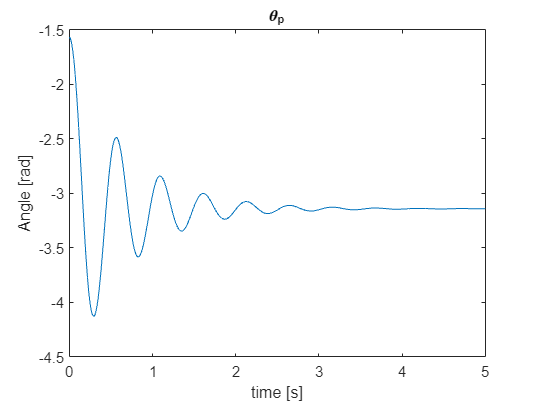


%  Runge-Kutta solver
[t, x] = ode45(odeFunHandler, tspan, x0);


% Plotting:
plot(t, x(:, 1));
title('\theta_p');
ylabel('Angle [rad]');
xlabel('time [s]');

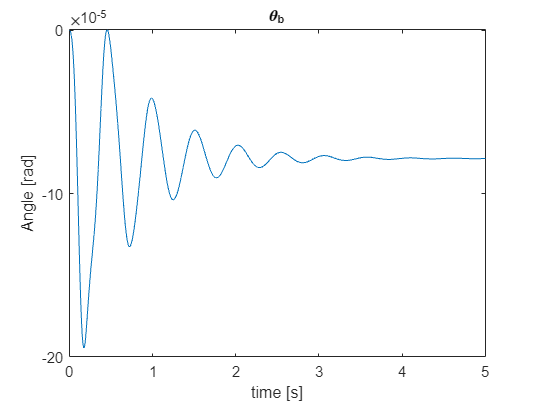


plot(t, x(:, 3))
title('\theta_b')
ylabel('Angle [rad]');
xlabel('time [s]');

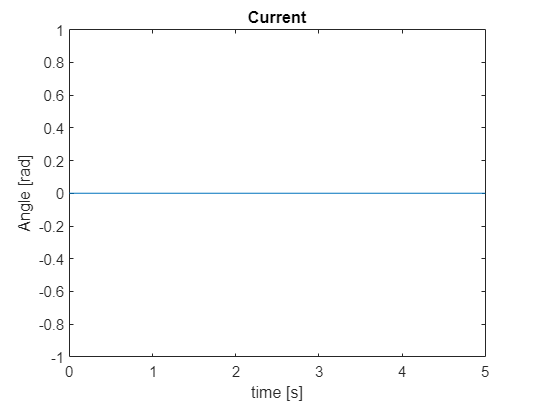


plot(t, x(:, 5))
title('Current')
ylabel('Angle [rad]');
xlabel('time [s]');

function dxdt = odeFun(x, l_B, l_P, I_B, I_P, L, m_P, B_B, B_P, R, g, K_t, K_e, K_lqr, B)
    dxdt = [
    x(2); 
    -(B_P*x(2) + g*m_P*sin(x(1)) + l_P^2*m_P*cos(x(1))*sin(x(1))*x(4)^2 - (l_B*l_P*m_P*cos(x(1))*(- m_P*sin(2*x(1))*x(4)*l_P^2*x(2) + l_B*m_P*sin(x(1))*l_P*x(2)^2 - B_P*x(2) + B_B*x(4) + K_t*x(5)))/(m_P*l_B^2 - m_P*l_P^2*cos(x(1))^2 + m_P*l_P^2 + I_B))/((m_P*l_P^2 + I_P)*((l_B^2*l_P^2*m_P^2*cos(x(1))^2)/((m_P*l_P^2 + I_P)*(m_P*l_B^2 - m_P*l_P^2*cos(x(1))^2 + m_P*l_P^2 + I_B)) - 1)); 
    x(4); 
    -(B_B*x(4) - B_P*x(2) + K_t*x(5) - l_P^2*m_P*sin(2*x(1))*x(4)*x(2) + l_B*l_P*m_P*sin(x(1))*x(2)^2 - (l_B*l_P*m_P*cos(x(1))*(m_P*cos(x(1))*sin(x(1))*l_P^2*x(4)^2 + B_P*x(2) + g*m_P*sin(x(1))))/(m_P*l_P^2 + I_P))/(((l_B^2*l_P^2*m_P^2*cos(x(1))^2)/((m_P*l_P^2 + I_P)*(m_P*l_B^2 - m_P*l_P^2*cos(x(1))^2 + m_P*l_P^2 + I_B)) - 1)*(m_P*l_B^2 - m_P*l_P^2*cos(x(1))^2 + m_P*l_P^2 + I_B)); 
    -(K_e*x(4) - 0 + R*x(5))/L
    ];
dxdt(5) = 0;
%dxdt = dxdt - (B*K_lqr*x);
end